**The iLQR on the cart and pole system**

Consider the cart-and-pole system here depicted:

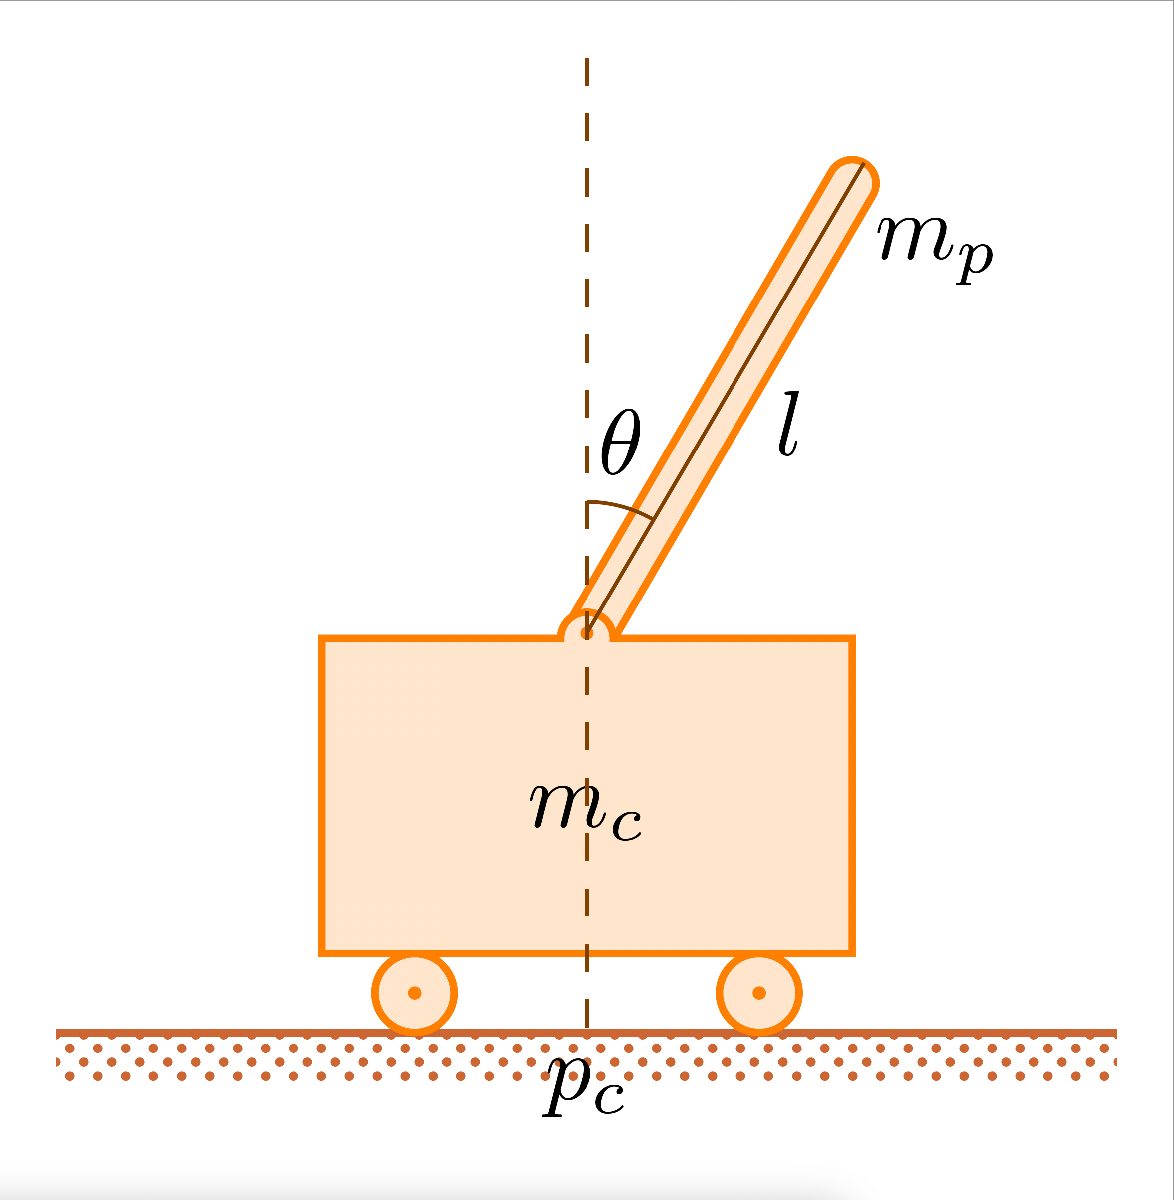

whose dynamics follows the following equations:


$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$



$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

1.Simulate the non linear cart and pole system applying the provided control input sequence $\bar{u}^{(k)}$ with a sample time of 0.005 sec. Record the resulting state trajectory $\bar{x}^{(k)}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectory.

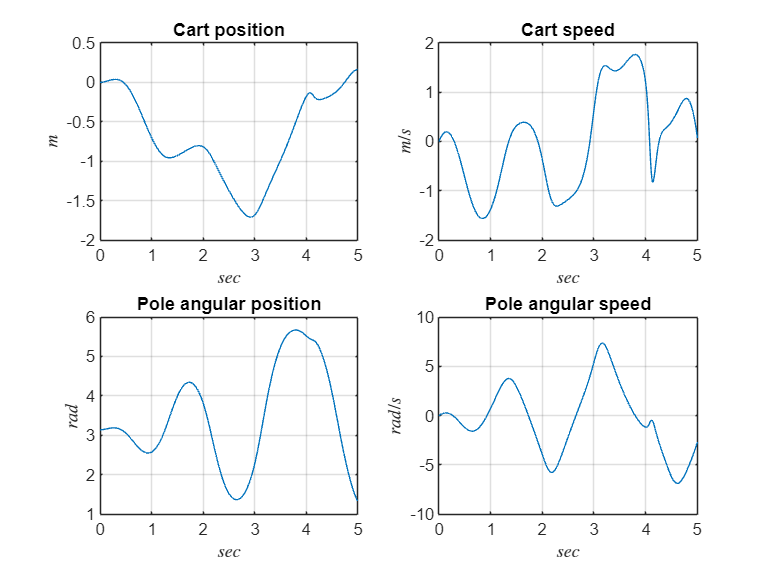

close all
clear
clc

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

load ilqr_u.mat

x0 = [0 0 pi 0];
Ts = 0;
for i=1:1:1000
    Ts = [Ts Ts(end)+0.005]; %#ok<*AGROW>
end

j1 = 1;

x_ilqr = x0;

for i=1:1:1000   %simulation of an initial tajectory provided by the professor

    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, input_traj(i)), [Ts(i) Ts(i+1)], x0);
   
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout(j1:j2, :) = x;
    tout(j1:j2, :) = t;
    
    x_ilqr = [x_ilqr; x(end, :)];

    j1 = j2;

    x0 = x(end, :);
end


close all
subplot(2,2,1);
plot(tout, xout(:,1));
xlim([0 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(tout, xout(:,2));
xlim([0 5]);
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(tout, xout(:,3));
xlim([0 5]);
grid on;
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

subplot(2,2,4);
plot(tout, xout(:,4));
xlim([0 5]);
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

Animation of the system

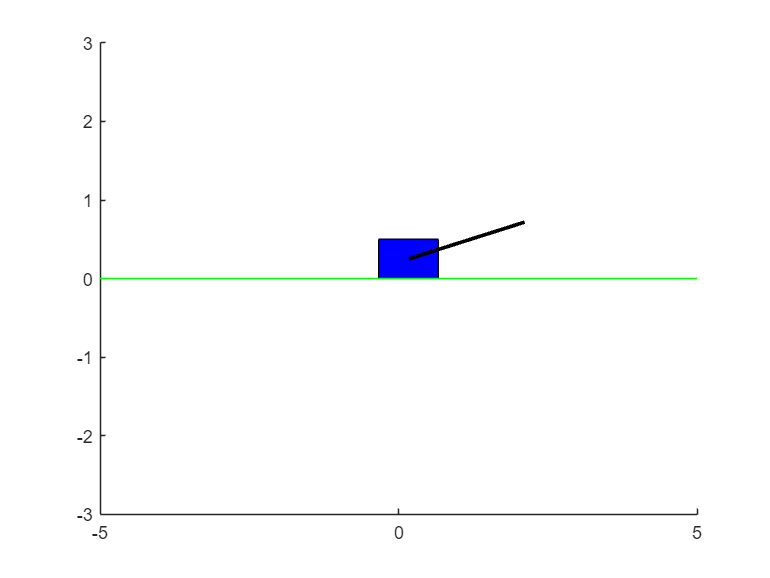

close all
animate_cartpole(Ts, x_ilqr);

2. Linearize the non-linear cart and pole system around the nominal state-input trajectories $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$previously obtained, and store the time-varying matrices of the linearized system$\{A(k),B(k)\}$

syms x1 x2 x3 x4 F;
d_x3 = x4;
d_x4 = (g*sin(x3)+ cos(x3)*((-F-mp*l*(x4^2)*sin(x3))/(mc+mp))-((mu_p*x4)/(mp*l))) / (l*((4/3)-((mp*(cos(x3)^2))/(mc+mp))));

d_x1 = x2;
d_x2 = (F+mp*l*((x4^2)*sin(x3)-d_x4*cos(x3)))/(mc+mp);


a_sym = jacobian([d_x1 d_x2 d_x3 d_x4], [x1 x2 x3 x4]);
b_sym = jacobian([d_x1 d_x2 d_x3 d_x4], F);


A_temp = subs(a_sym, [x1 x2 x3 x4 F], [x_ilqr(1, :) input_traj(i,1)]);
A = double(A_temp);
B_temp = subs(b_sym, [F x3], [input_traj(1) x_ilqr(1,3)]);
B = double(B_temp);

for i=2:1:1000   %computing all the linearized matrices for every step of the previos simulation
    
    A_temp = subs(a_sym, [x1 x2 x3 x4 F], [x_ilqr(i, :) input_traj(i,1)]);
    A_ipiu1 = double(A_temp);
    A = [A A_ipiu1];

    B_temp = subs(b_sym, [F x3], [input_traj(i,1) x_ilqr(i,3)]);
    B_ipiu1 = double(B_temp);
    B = [B B_ipiu1];
end

3. Compute the discrete-time homogeneous representation of the linear time-varying cart and pole system obtained at point 2 and store the matrices of the homogeneous representation

C = eye(4);
D = zeros(4,1);

A_cont = A(:, 1:4);
B_cont = B(:, 1);
sys_c = ss(A_cont, B_cont, C, D);
sys_d = c2d(sys_c, 0.005);

A_d = sys_d.A;
B_d = sys_d.B;

for i=1:1:999
    
    i1 = i*4+1;
    i2 = i*4+4;
    A_cont = A(:, i1:i2);
    B_cont = B(:, i);
    sys_c = ss(A_cont, B_cont, C, D);
    sys_d = c2d(sys_c, 0.005);

    A_d = [A_d sys_d.A];
    B_d = [B_d sys_d.B];
end

4. Assume $Q=I$ and $R=1$, the cost matrices for a swing up cart and pole task, and compute $\hat{Q}(k)=$$\left\lbrack \begin{array}{cc}
Q & -{q^{\left(k\right)} }^{\top } \\
{-q}^{\left(k\right)}  & d^{\left(k\right)} 
\end{array}\right\rbrack$where $$\bar{x}^{{(k)}^\top} Q \bar{x}^{(k)}=d^{(k)}$$ and $$2\bar{x}^{{(k)}^\top} Q=2 q^{{(k)}^\top}$$for the entire nominal state trajectory  and store them

Q = eye(4,4);
R = 1;

d_k = x_ilqr(1, :)*Q*(x_ilqr(1, :)');
q_k = x_ilqr(1,:)*Q;
q_k_T = q_k';
Q_hat = [ Q      -q_k_T;
         -q_k    d_k];

sym_chek = issymmetric(Q_hat);   %check the simmetry of the matrix Q_hat
ispos = all(eig(Q_hat)>0);  %check if the matrix Q_hat is definded positive
ep = 10e-6;

while(ispos ~= 1)
    
    Q_hat = Q_hat + ep*eye(5,5);

    ispos = all(eig(Q_hat) > 0);

    ep = 10*ep;
end


for i=2:1:1000

    d_k = x_ilqr(i, :)*Q*(x_ilqr(1, :)');
    q_k = x_ilqr(i,:)*Q;
    q_k_T = q_k';
    Q_hat_temp = [ Q -q_k_T; -q_k d_k];
    
    sym_chek = issymmetric(Q_hat_temp);
    ispos = all(eig(Q_hat_temp) >= 0);
    ep = 10e-6;

    while(ispos ~= 1)
    
        Q_hat_temp = Q_hat_temp + ep*eye(5,5);

        ispos = all(eig(Q_hat_temp) > 0);

        ep = 10*ep;
    end

    Q_hat = [Q_hat Q_hat_temp];
end

5. Solve the finite-horizon LQR problem on the linearized version of the system and store the control gain matrices $\{K(k)\}$. Assume that $P_H =\left\lbrack \begin{array}{cc}
I & 0\\
0 & 0
\end{array}\right\rbrack$.

P_h = [eye(4,4)   zeros(4,1);
       zeros(1,4)         0];

A_cinque = [A_d(:, 3997:4000) zeros(4,1);
            zeros(1,4)            1];
B_cinque = [B_d(:, 1000); 0];

Q_cinque = Q_hat(:, 4996:5000);

P_k = A_cinque' * P_h * A_cinque + Q_cinque - A_cinque' * P_h * B_cinque * (inv(R + B_cinque' * P_h * B_cinque)) * B_cinque' * P_h * A_cinque;
K_k = (inv(R + B_cinque' * P_h * B_cinque)) * B_cinque' * P_h * A_cinque;

for i=999:-1:1

    ia1 = 4*i-3;
    ia2 = 4*i;
    iq1 = 5*i-4;
    iq2 = 5*i;
    A_cinque = [A_d(:, ia1:ia2) zeros(4,1); zeros(1,4) 1];
    B_cinque = [B_d(:, i); 0];
    Q_cinque = Q_hat(:, iq1:iq2);
    P_k_uno = P_k;

    P_k = A_cinque' * P_k_uno * A_cinque + Q_cinque - A_cinque' * P_k_uno * B_cinque * (inv(R + B_cinque' * P_k_uno * B_cinque)) * B_cinque' * P_k_uno * A_cinque;
    K_k_temp = (inv(R + B_cinque' * P_k_uno * B_cinque)) * B_cinque' * P_k_uno * A_cinque;

    K_k = [K_k_temp; K_k];

end

6. Simulate the non-linear cart and pole system applying the computed control gain matrices $\{K(k)\}$ with a sample time of 0.005 sec. Record the resulting state and control input trajectory $\{\bar{x}^{(k)},\bar{u}^{(k)}\}$with an initial state of $\theta =180$, $\dot{\theta}=0$, $p_c=0$, $\dot{p}_c=0$. Plot the resulting trajectories

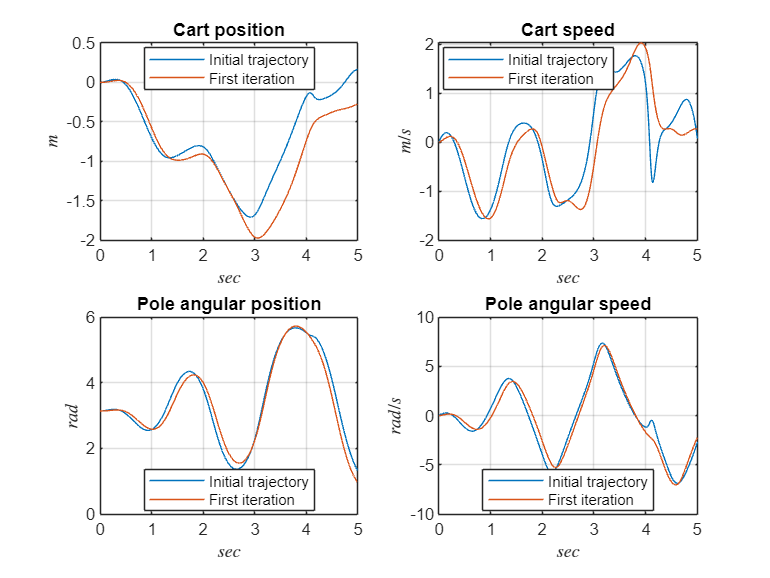

x0 = [0 0 pi 0]';
x_hat = [x0 - (x_ilqr(1,:)') ; 1];
U = -K_k(1,:)*x_hat;

Ts = 0;
for i=1:1:1000
    Ts = [Ts Ts(end)+0.005];
end

j1 = 1;

for i=1:1:999

    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, U), [Ts(i) Ts(i+1)], x0);
   
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout_ilqr(j1:j2, :) = x;
    tout_ilqr(j1:j2, :) = t;

    j1 = j2;

    x0 = x(end, :);
    x_hat = [x0' - (x_ilqr(i+1,:)') ; 1];
    U = -K_k(i+1,:)*x_hat;
end

close all
subplot(2,2,1);
plot(tout, xout(:,1));
hold on
plot(tout_ilqr, xout_ilqr(:,1));
xlim([0 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
legend("Initial trajectory", "First iteration", Location="best");
title("Cart position");

subplot(2,2,2);
plot(tout, xout(:,2));
hold on
plot(tout_ilqr, xout_ilqr(:,2));
xlim([0 5]);
grid on
legend("Initial trajectory", "First iteration", Location="best");
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(tout, xout(:,3));
hold on
plot(tout_ilqr, xout_ilqr(:,3));
xlim([0 5]);
grid on;
legend("Initial trajectory", "First iteration", Location="best");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

subplot(2,2,4);
plot(tout, xout(:,4));
hold on
plot(tout_ilqr, xout_ilqr(:,4));
xlim([0 5]);
grid on
legend("Initial trajectory", "First iteration", Location="best");
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

function dxdt = cart_pend_for(t, x, g, mp, mc, l, mu_p, U) %#ok<*INUSD>

  dxdt = zeros(4,1);

  dxdt(1) = x(2);
  dxdt(2) = (U+mp*l*((x(4)^2)*sin(x(3))-((g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp)))))*cos(x(3))))/(mc+mp);
  dxdt(3) = x(4);
  dxdt(4) = (g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp))));

end

function animate_cartpole(t, states)
    % Parameters for drawing
    cart_width = 1.0;
    cart_height = 0.5;
    pole_length = 2.0;

    figure;

    for i = 1:length(t)
        % Clear the figure
        clf;

        x = states(i, 1);  % Cart position
        theta = states(i, 3);  % Pole angle

        % Compute the pole's coordinates
        pole_x = x + pole_length * sin(theta);
        pole_y = cart_height / 2 + pole_length * cos(theta);

        % Cart
        rectangle('Position', [x - cart_width / 2, 0, cart_width, cart_height], 'FaceColor', [0, 0, 1]);

        % Pole
        line([x, pole_x], [cart_height / 2, pole_y], 'LineWidth', 2, 'Color', [0, 0, 0]);

        % Ground
        line([-10, 10], [0, 0], 'Color', [0, 1, 0]);


        xlim([-5, +5]);
        ylim([-pole_length - 1, pole_length + 1]);

        pause(0.01);
    end
end